对数据进行筛选和区分

thresh_dip = 0.3;
thresh_ref = 0.3;
len_thresh = 5;
R_thresh = 0.89;

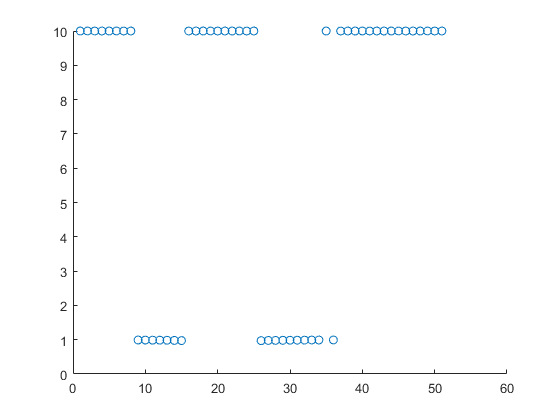

data_fp = fitdata;

lefthalf = fitdata(find(fitf < D));
righthalf = fitdata(find(fitf >= D));

I_peak = -2*C*W/(4*(W^2))+B;

I_dip = abs(fitdata - B);
I_ref = abs(fitdata - I_peak);


span_dip = max(I_dip)-min(I_dip);
span_ref = max(I_ref)-min(I_ref);

data_fp(find(I_dip < thresh_dip*span_dip)) = 10;
data_fp(find(I_ref < thresh_ref*span_ref)) = 10;

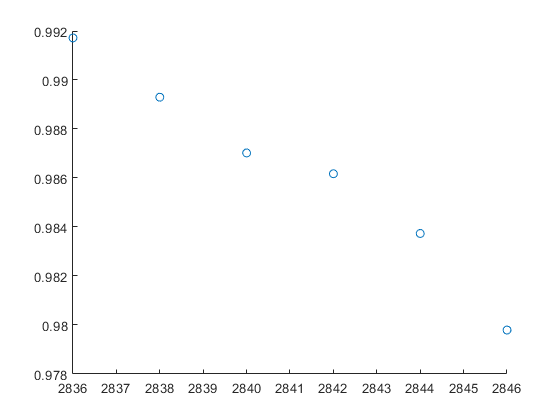

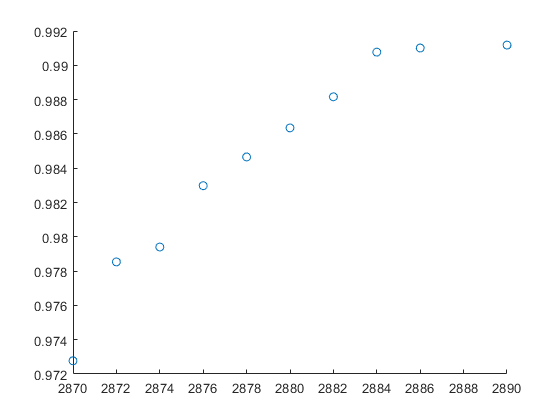

D1 = fitf(find(data_fp == min(data_fp(find(fitf<D)))));
D2 = fitf(find(data_fp == min(data_fp(find(fitf>D)))));


data_fp_L = data_fp(find(fitf<D1));
data_fp_R = data_fp(find(fitf>=D2));

freq_fp_L = f(fitf<D1);
freq_fp_R = f(fitf>=D2);

data_fpfit_L = data_fp_L(data_fp_L ~= 10);
data_fpfit_R = data_fp_R(data_fp_R ~= 10);

freq_fpfit_L = freq_fp_L((data_fp_L ~= 10));
freq_fpfit_R = freq_fp_R((data_fp_R ~= 10));

拟合并迭代得到直线

flag_L = 1;
flag_R = 1;
tempL = [freq_fpfit_L',data_fpfit_L'];
tempR = [freq_fpfit_R',data_fpfit_R'];
while flag_L + flag_R > 0
    if flag_L == 1
        L1 = tempL(1:end-1,:);
        L2 = tempL(2:end,:);
        [ft_L1,gof_L1] = fit(L1(:,1),L1(:,2),'poly1');
        [ft_L2,gof_L2] = fit(L2(:,1),L2(:,2),'poly1');
        R_L1 = gof_L1.rsquare; R_L2 = gof_L2.rsquare;
        if R_L1>R_L2
            R_L = R_L1;
            ft_L = ft_L1;
            tempL = L1;
        else
            R_L = R_L2;
            ft_L = ft_L2;
            tempL = L2;
        end
        if (R_L > R_thresh)||(length(tempL) == len_thresh)
            flag_L = 0;
        end        
    end    
    if flag_R == 1
        R1 = tempR(1:end-1,:);
        R2 = tempR(2:end,:);
        [ft_R1,gof_R1] = fit(R1(:,1),R1(:,2),'poly1');
        [ft_R2,gof_R2] = fit(R2(:,1),R2(:,2),'poly1');
        R_R1 = gof_R1.rsquare; R_R2 = gof_R2.rsquare;
        if R_R1>R_R2
            R_R = R_R1;
            ft_R = ft_R1;
            tempR = R1;
        else
            R_R = R_R2;
            ft_R = ft_R2;
            tempR = R2;
        end
        if (R_R > R_thresh)||(length(tempR) == len_thresh)
            flag_R = 0;
        end  
    end
end

k_L = ft_L.p1; k_R = ft_R.p1;
b_L = ft_L.p2; b_R = ft_R.p2;

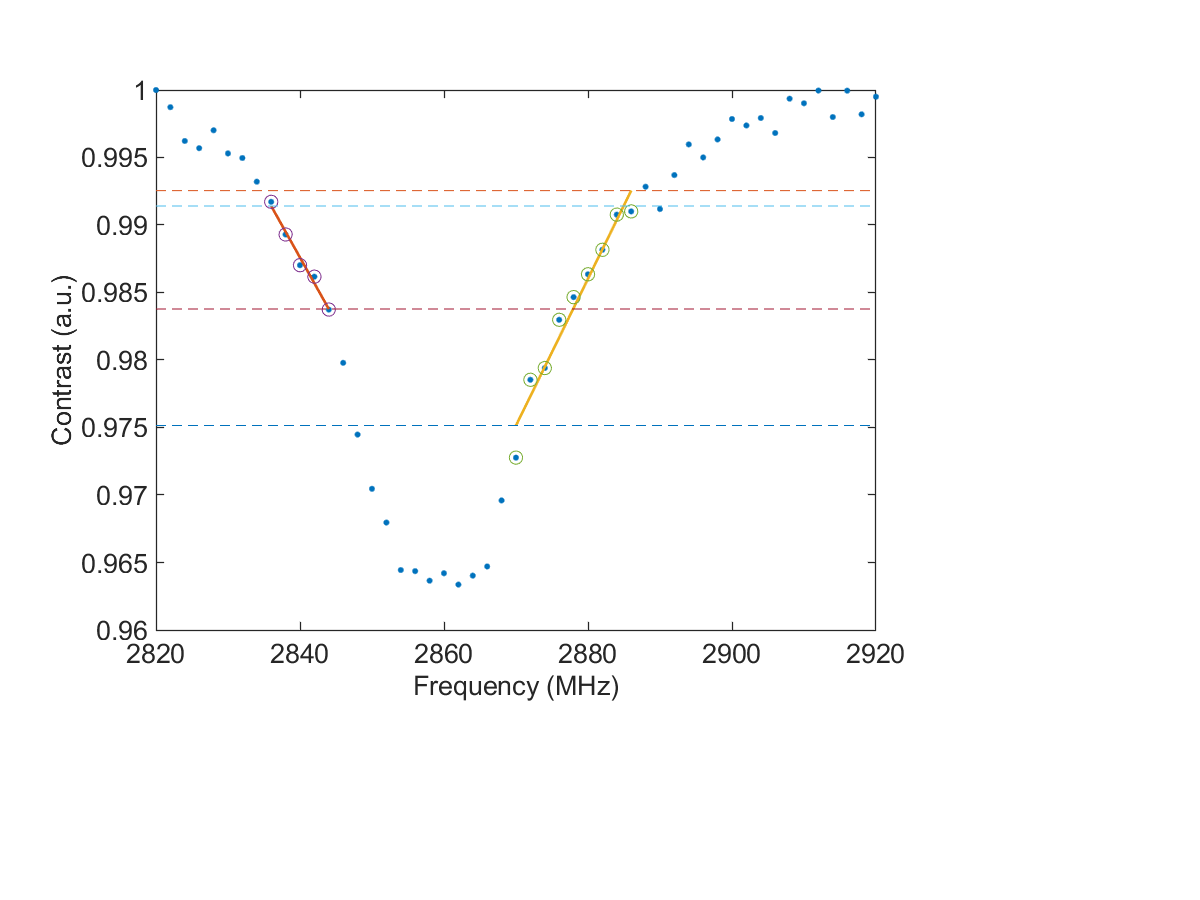

h1 = figure;
    set(h1,'unit','pixels','position',[0 0 1200 900],'color',[1,1,1]); 

scatter(fitf,fitdata,'Marker','.','SizeData',200)
hold on
plot(tempL(:,1),k_L.*tempL(:,1)+b_L,'LineWidth',2);
plot(tempR(:,1),k_R.*tempR(:,1)+b_R,'LineWidth',2);
scatter(tempL(:,1),tempL(:,2),'Marker','o','SizeData',100)
scatter(tempR(:,1),tempR(:,2),'Marker','o','SizeData',100)
plot([min(fitf),max(fitf)],[min(tempL(:,1))*k_L+b_L,min(tempL(:,1))*k_L+b_L],'LineStyle','--')
plot([min(fitf),max(fitf)],[max(tempL(:,1))*k_L+b_L,max(tempL(:,1))*k_L+b_L],'LineStyle','--')
plot([min(fitf),max(fitf)],[min(tempR(:,1))*k_R+b_R,min(tempR(:,1))*k_R+b_R],'LineStyle','--')
plot([min(fitf),max(fitf)],[max(tempR(:,1))*k_R+b_R,max(tempR(:,1))*k_R+b_R],'LineStyle','--')
FigureFormat('Frequency (MHz)','Contrast (a.u.)',[])

在直线上选点

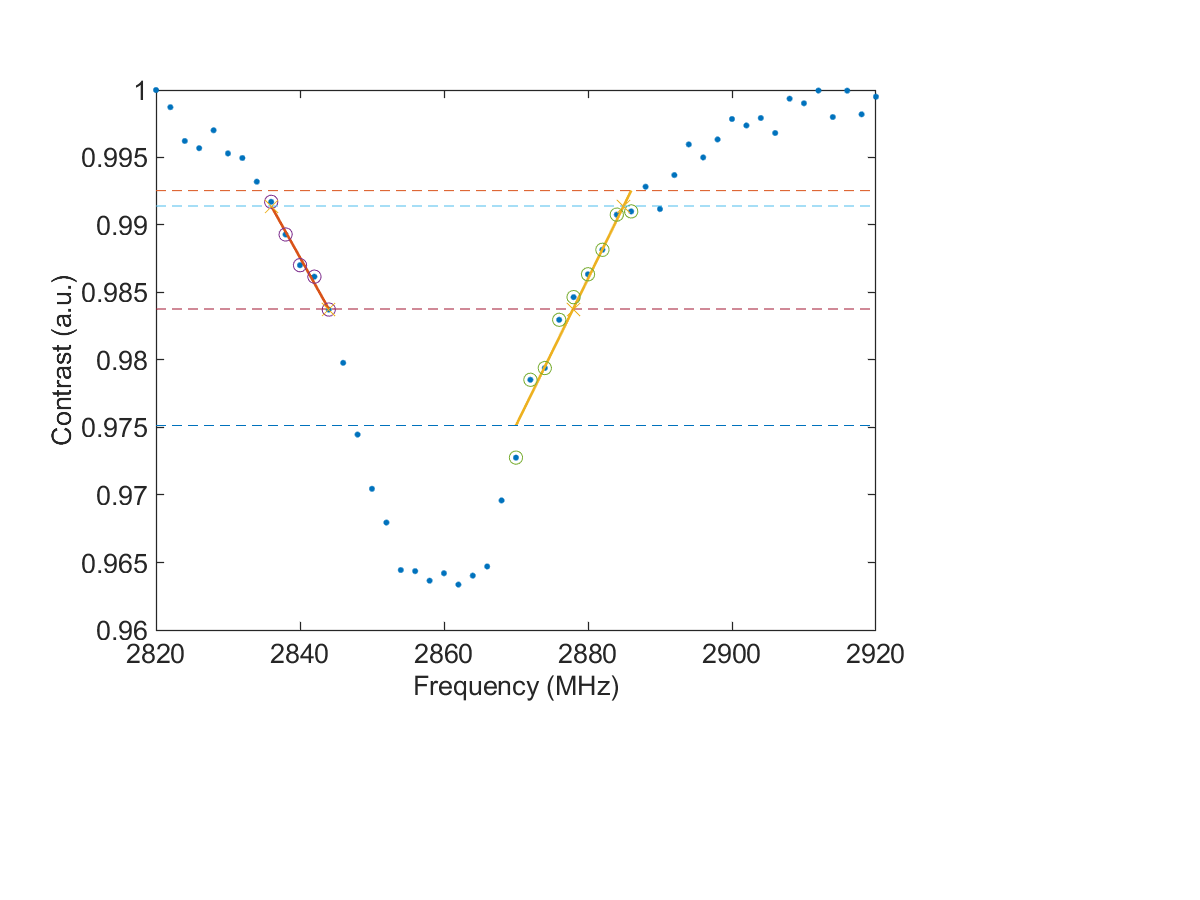

Y_max = min([min(tempL(:,1)*k_L+b_L),max(tempR(:,1)*k_R+b_R)]);
Y_min = max([max(tempL(:,1)*k_L+b_L),min(tempR(:,1)*k_R+b_R)]);
Omega(1) = (Y_max-b_L)/k_L;
Omega(2) = (Y_min-b_L)/k_L;
Omega(3) = (Y_min-b_R)/k_R;
Omega(4) = (Y_max-b_R)/k_R;
scatter(Omega,[Y_max,Y_min,Y_min,Y_max],'Marker','x','SizeData',200)